# Example 1.6

% Jonghwan Lee, Jan 2021

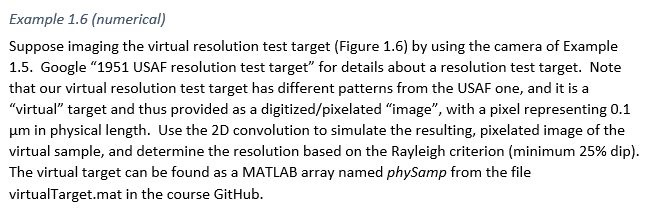

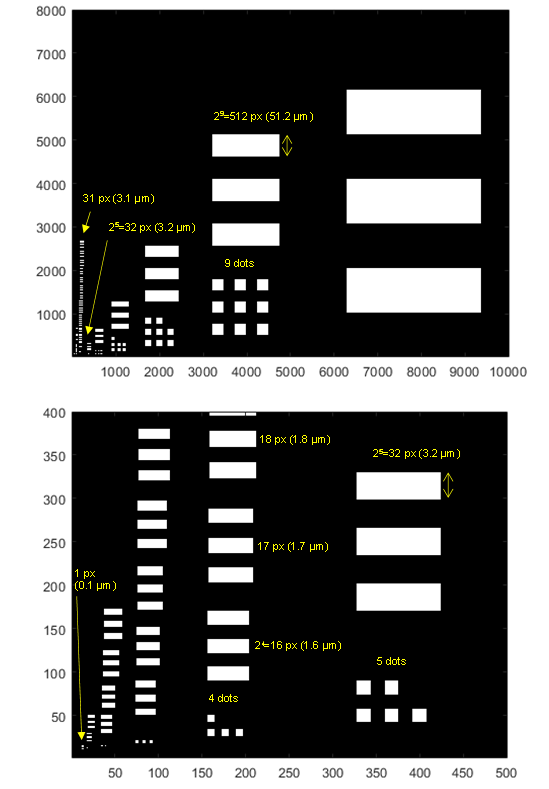

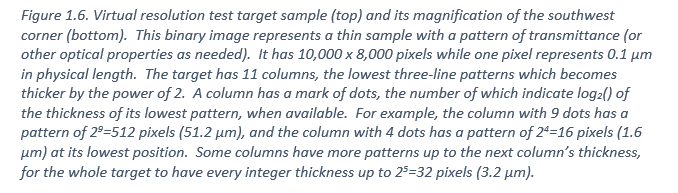

## Prepare variables.

All lengths are in [um].

clear;
nx = 100;  ny = 80;  % number of sampling points (pixels of the camera)
dxSamp = 5;  % the sampling interval on the focal plane [um]

Load the virtual target.

load("virtualTarget.mat","phySamp");  % phySamp : the virtual resolution test target
phySamp = double(phySamp);  % convert the boolean array to a double array for further computation
[nxp,nyp] = size(phySamp)  % size of the physical sample [pixels]

nxp = 10000

nyp = 8000

dxp = 0.1;  % um per pixel of the physical sample
disp(['Sample size (um) = ' mat2str([nxp nyp]*dxp)])

Sample size (um) = [1000 800]


Preview the virtual target.

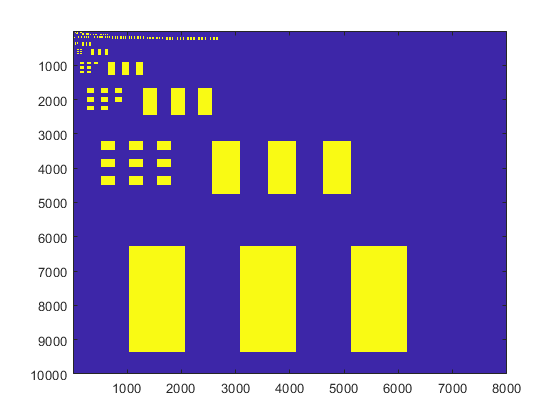

figure;
imagesc(phySamp);

- The x and y axes are opposite!

- The y axis direction is inverted.

- The x and y scales are not identical (not isotropic).

Fix the visualization.

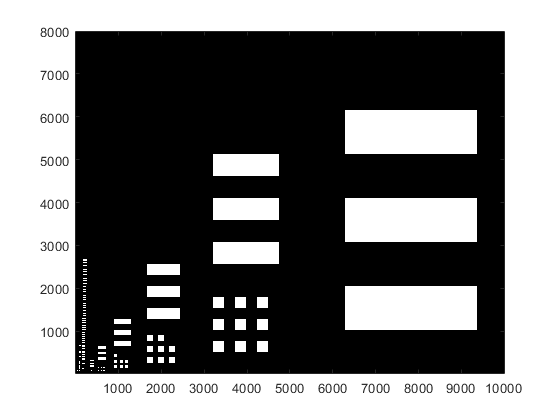

figure;  colormap(gray);
imagesc(phySamp');  % transpose the 2D array to make the x axis to be horizontal
set(gca,'ydir','normal');  % set the y axis direction normal
axis image;  % set the axes isotropic

Zoom in

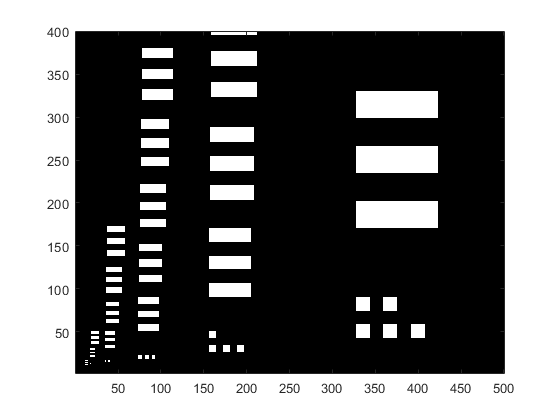

figure;  colormap(gray);
imagesc(phySamp(1:500,1:400)');
set(gca,'ydir','normal');
axis image;

## Implement the convolution.

Repeat the averaging for each of the kernel position on the sample plane.

dxKernPhy = round(dxSamp/dxp);  % the kernel size in terms of physical pixels 

img = zeros(nx,ny);  % empty array as a resulting image

ixKern = 0;  iyKern = 0;  % starting position of the sampling kernel
for iy=1:ny
    for ix=1:nx
        
        % for each (ix,iy)th pixel of the image, average the corresponding area (kernel) of the virtual sample
        sam1 = phySamp(ixKern+(1:dxKernPhy),iyKern+(1:dxKernPhy));  % extract the piece of the virtual sample
        img(ix,iy) = mean(sam1(:));  % average the information within the piece
        
        ixKern = ixKern + dxKernPhy;  % update ix for the next kernel position in X
    end
    iyKern = iyKern + dxKernPhy;  ixKern = 0;  % update iy and ix for the next kernel position
end

Show the resulting image.

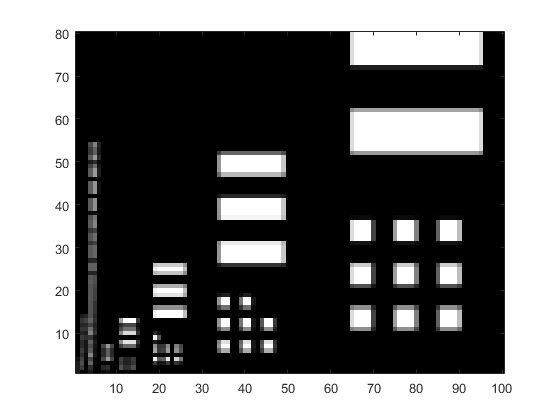

figure;  colormap(gray);

imagesc(img');
set(gca,'ydir','normal');
axis image;

## Use convn().

Make a 2D array for the kernel.

kern = ones(dxKernPhy,dxKernPhy);
kern = kern/sum(kern(:));  % normalize the kernel when using convn()

Perform convolution of `phySamp` with the kernel.

phySampConv = convn(phySamp,kern,'same');  

Pick the data from the center of each "pixel" on the sample plane.

dxSamPhy = round(dxSamp/dxp);  % the sampling interval in terms of the physical pixel number
img2 = phySampConv(round(dxSamPhy/2):dxSamPhy:end,round(dxSamPhy/2):dxSamPhy:end);

Crop the resulting image if it is larger than the FOV.

if size(img2,1) > nx
    img2 = img2(1:nx,:);
end
if size(img2,2) > ny
    img2 = img2(:,1:ny);
end

Show the resulting image.

figure;  colormap(gray);
imagesc(img2');
set(gca,'ydir','normal');
axis image;

Compare the difference between two methods.

disp(['Difference = ' num2str(mean((img(:)-img2(:)).^2),3)]);

Difference = 2.37e-28


## Determine the resolution.

When visually inspecting, the lines of the 6-dots column is clear (2^6=64 pixels or 6.4-um).  Thus, the resolution is better than 6.4 um, similar to the kernel size 5 um.

More quantitatively, we can use the Rayleigh criterion (minimum 25% dip).

To extract the intensity (brightness) profile along the line passing through the lines of the 6-dots column, you can use MATLAB UI of the figure window to find the x position of the center of the lines.

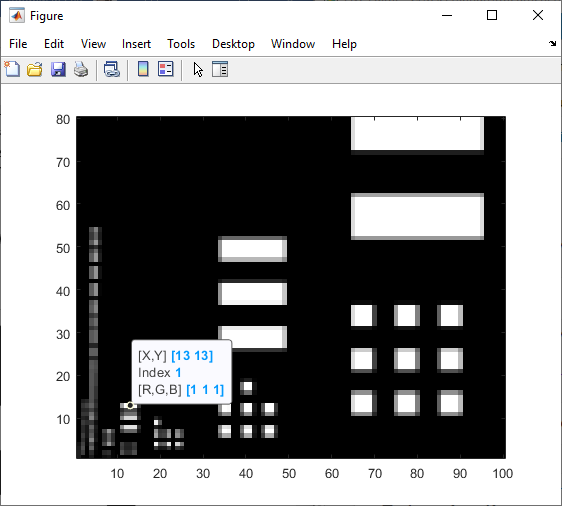

Similarly, we can find the x position of the 5-dots column.

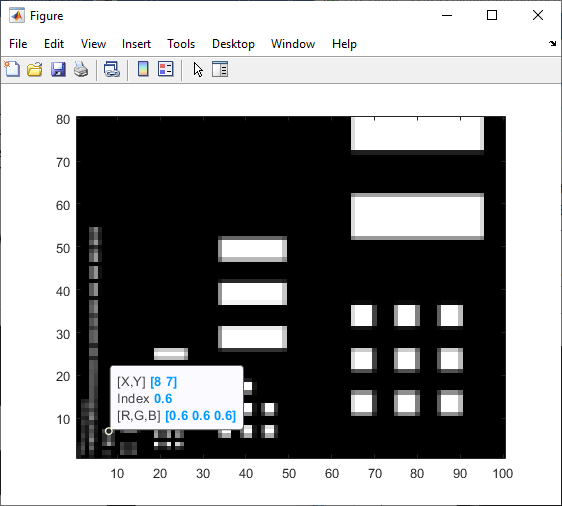

ix64 = 13;  % the center X position of the 6.4-um pattern
ix32 = 8;  % the center X position of the 3.2-um pattern 

Extract and show the intensity profiles.

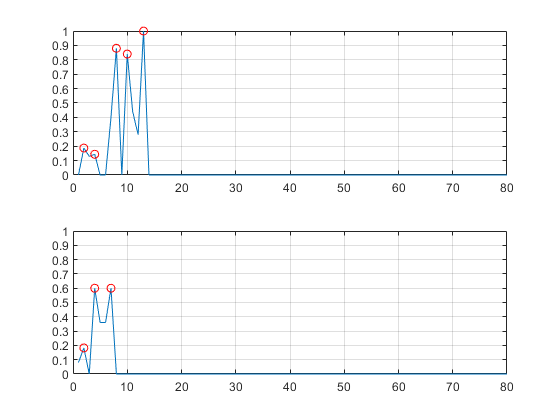

figure;
subplot(211);  
    I = img2(ix64,:);  % 1D array extracted from the 2D array.
    plot(I);
    [pks,locs] = findpeaks(I);  % find peaks.
    line(locs,pks,'linestyle','none','marker','o','color','r');
    ylim([0 1]);  set(gca,'ytick',(0:.1:1));  grid on;
subplot(212);  % repeat the same for the 3.2-um pattern
    I = img2(ix32,:);
    plot(I);
    [pks,locs] = findpeaks(I);
    line(locs,pks,'linestyle','none','marker','o','color','r');
    ylim([0 1]);  set(gca,'ytick',(0:.1:1));  grid on;

- We can see 3 peaks in the 6.4-um pattern but not in the 3.2-um pattern.